# **Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clearvars
close all
clear all;clc
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - Loglikelihood

Ground Truth - 25e9

Measurement1 = uq_SimplySupportedBeam([25e9 25e3]);
Measurement2 = Beam_elongation([25e9]);
Measurement_All = [Measurement1 Measurement2] ;
myData.y = Measurement_All;
size(myData.y)

ans =      1     2


myData.Name = 'Measurement on 29 points along the beam';
%myLogLikeli = @(params,y)  LL1(params,y(:,1))   + LL2(params,y(:,2));
myLogLikeli = @(params,y)  LL2(params,y(:,2));

## 3 PRIOR DISTRIBUTION OF THE MODEL PARAMETERS



PriorOpts.Marginals(1).Name = 'E'; % Young's modulus
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments = [30 4.5]*1e9 ; % (N/m^2)

% PriorOpts.Marginals(2).Name = 'p'; % point load
% PriorOpts.Marginals(2).Type = 'Gaussian';
% PriorOpts.Marginals(2).Moments = [30e3 5e3]; % (N)

% PriorOpts.Marginals(2).Name = 'P'; % point load
% PriorOpts.Marginals(2).Type = 'Gaussian';
% PriorOpts.Marginals(2).Moments = [40e3 5e3] ; % (N)


% 
% PriorOpts.Marginals(4).Name = 'Sigma2_1';               % sigma2_1
% PriorOpts.Marginals(4).Type = 'Uniform';
% sigma2_1  = mean(Measurement1,'all').*0.01;
% PriorOpts.Marginals(4).Parameters  = [0 sigma2_1^2];
% PriorOpts.Marginals(4).Bounds  = [0 inf];



PriorOpts.Marginals(2).Name = 'Sigma2_2';               % sigma2_1
PriorOpts.Marginals(2).Type = 'Uniform';
sigma2_2  = mean(Measurement2,'all').*0.01;
PriorOpts.Marginals(2).Parameters  = [0 sigma2_2^2];


myPriorDist = uq_createInput(PriorOpts);

## 6 -  BAYESIAN ANALYSIS


Starting AIES...

|                              |   1.00%|#                             |   2.00%|#                             |   3.00%|#                             |   4.00%|##                            |   5.00%|##                            |   6.00%|##                            |   7.00%|##                            |   8.00%|###                           |   9.00%|###                           |  10.00%|###                           |  11.00%|####                          |  12.00%|####                          |  13.00%|####                          |  14.00%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.00%|#####                         |  18.00%|######                        |  19.00%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.00%|#######                       |  23.00%|#######                       |  24.00%|########            

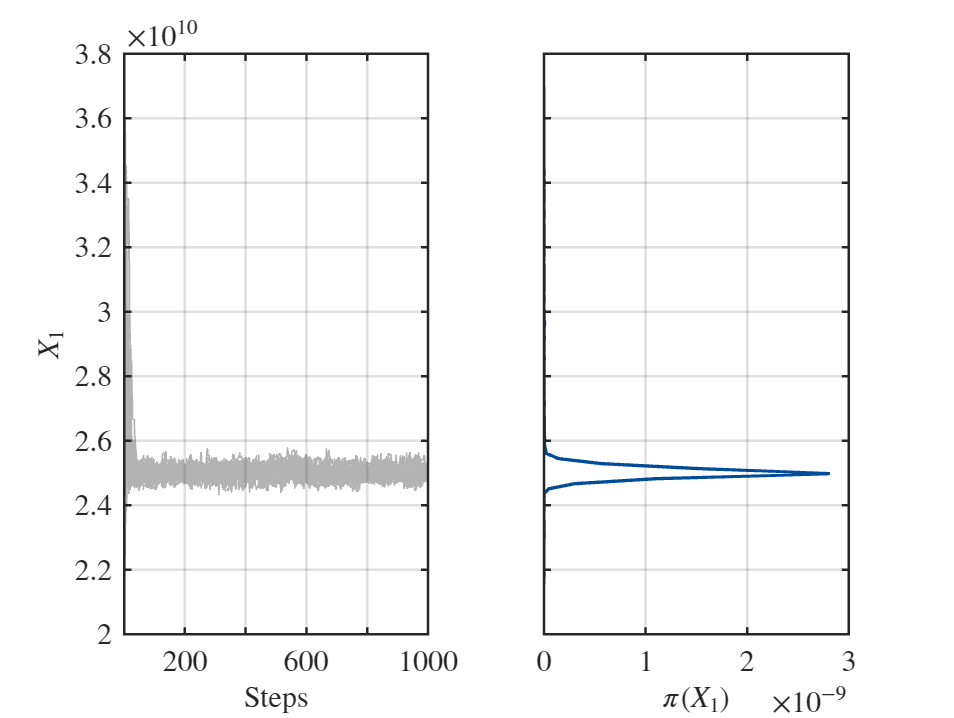

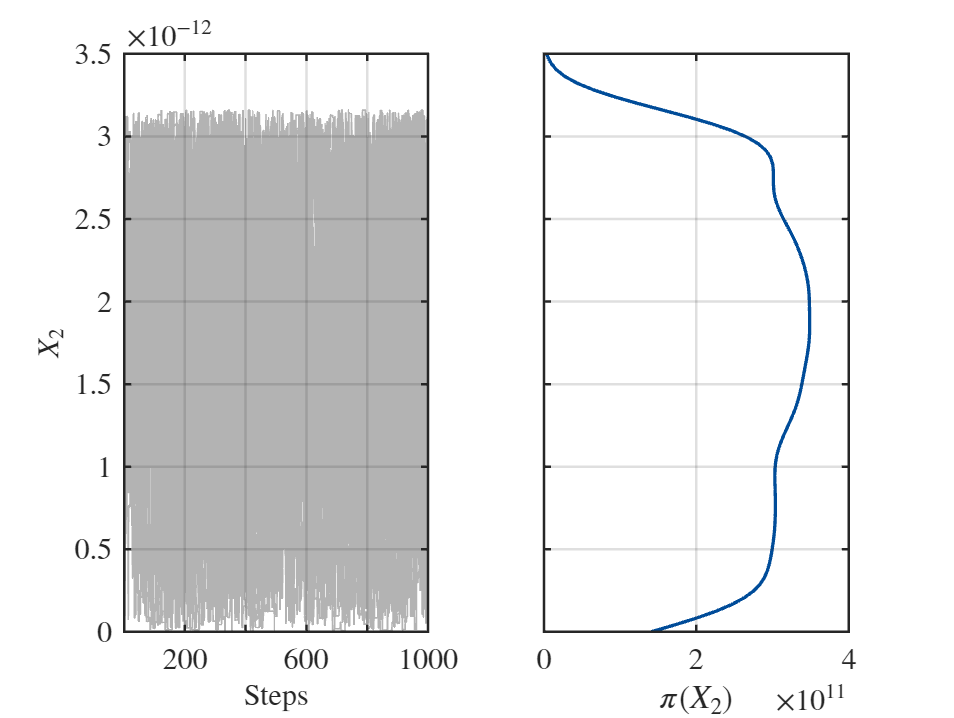


Finished AIES!



Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 1000;
Solver.MCMC.NChains = 30;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

uq_print(BayesAnalysis)

%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:00:51
   Number of sample points:                       3.00e+04

%------------------- Posterior Marginals
---------------------------------------------------------------
| Parameter | Mean    | Std     | (0.025-0.97) Quant. | Type  |
---------------------------------------------------------------
| E         | 2.5e+10 | 1.7e+08 | (2.5e+10 - 2.5e+10) | Model |
| Sigma2_2  | 1.6e-12 | 8.9e-13 | (9.2e-14 - 3.1e-12) | Model |
---------------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | Mean    | Parameter Type |
----------------------------------------
| E         | 2.5e+10 | Model          |
| Sigma2_2  | 

%uq_display(BayesAnalysis)